## Model

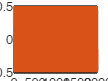

signed = 1;
word_len = 16;
frac_len = 7;
T = numerictype(signed, word_len, frac_len);

ns = 2000;
sine = dsp.SineWave(0.5, 375, 'SampleRate',8000,'SamplesPerFrame',ns);
s = fi(sine(), T);
cosine = dsp.SineWave(0.5, 375, pi/2, 'SampleRate',8000,'SamplesPerFrame',ns);
c = fi(cosine(), T);

plot([s c])

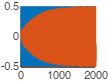


L = 2;
lms = dsp.LMSFilter(L,'Method','LMS');

[mumaxlms,mumaxmselms] = maxstep(lms,c.data);
lms.StepSize  = mumaxmselms/10;
[y,elms,wlms] = lms(s,c);
plot([c y])

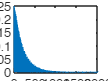


reset(lms);
release(lms);

[mse, meanw, w, tracek] = msesim(lms, s.data, c.data);

plot(mse)

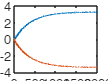

plot(meanw)

## Sim inputs

save_dec_txt(s, T, "data/input.txt");
save_dec_txt(c, T, "data/desired.txt");
fi(lms.StepSize,T).hex

ans = '003c'

## Simulation

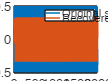

out = load_dec_txt("data/output.txt", T);
plot([c out])
legend('Original signal', 'Recovered signal')

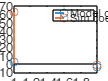


weights = load_dec_txt("data/weights.txt", T);
stem([wlms weights.data]);
legend('Model coeffs', 'Sim coeffs')

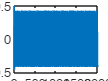


error = load_dec_txt("data/error.txt", T);
plot(error)